Q-2

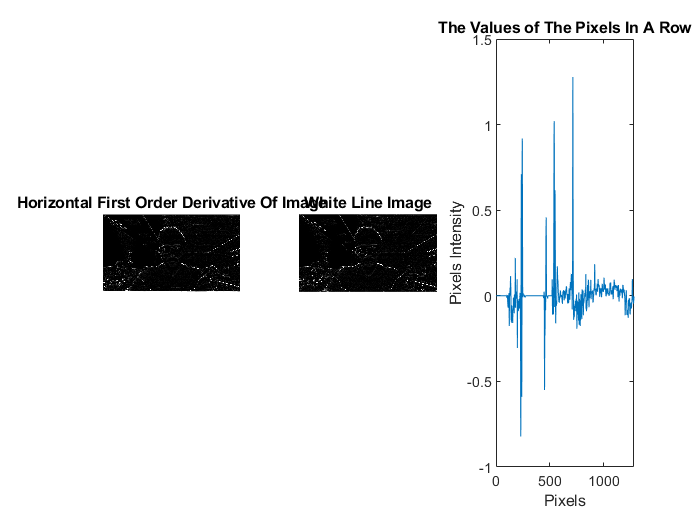

ahmet=imread('ahmet.jpg');
ahmet=im2double(ahmet);
ahmet_gray=rgb2gray(ahmet);
subplot(1,3,1)
imshow(ahmet_gray)
title('Double Grayscale Image','fontsize', [11])
 
filter=[1 2 1;0 0 0;-1 -2 -1];
image_first_derivative=imfilter(ahmet_gray,filter);
row_derivative=image_first_derivative(150,:);
 
 
subplot(1,3,2)
imshow(image_first_derivative)
title('Horizontal First Order Derivative Of Image','fontsize', [11])
 
[a,b]=size(row_derivative);
a=1:b; 

subplot(1,3,3)
plot(a,row_derivative)
title('The Values of The Pixels In A Row','fontsize', [12])
xlabel("Pixels")
ylabel("Pixels Intensity")
filter=[1 2 1;0 0 0;-1 -2 -1];

image_first_derivative=imfilter(ahmet_gray,filter);
row_derivative=image_first_derivative(150,:);
derivative_whiteline=image_first_derivative;
derivative_whiteline(150,:)=1; 
[a,b]=size(row_derivative);
a=1:b; 
 
subplot(1,3,1)
imshow(image_first_derivative)
title('Horizontal First Order Derivative Of Image','fontsize', [11])

subplot(1,3,2)
imshow(derivative_whiteline)
title('White Line Image','fontsize', [11])

subplot(1,3,3)
plot(a,row_derivative)
title('The Values of The Pixels In A Row','fontsize', [11])
xlabel('Pixels')
ylabel('Pixels Intensity')